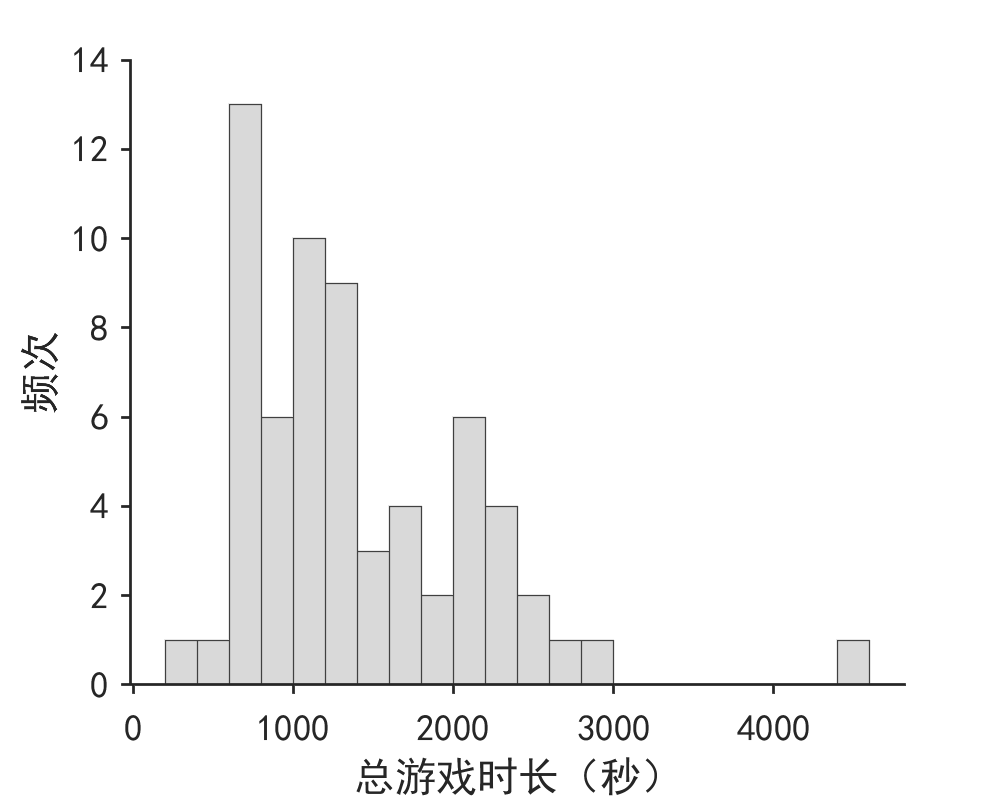

clear
initUtility
importData
figure('Position', [0 0 500 400])
T(T.Chapter == 3, :) = [];
T.sum = T.Time2Initiate + T.Time2Win + T.Time4Revisit;
summaryTable = groupsummary(T, {'SubNo'}, 'sum', 'IncludeEmptyGroups',true);
histogram(summaryTable.sum_sum, 'BinWidth',200, 'FaceColor',[0.75 0.75 0.75], 'EdgeColor',[0.25 0.25 0.25])
set_figure_prop
legend off
xlabel('总游戏时长（秒）')
ylabel('频次')

clear
importData
X = Q{:, surveyLabel};
[coeff,score,~, ~, explained, ~] = pca(zscore(X));

% save the first 2 components
Q.GameFreq = zscore(score(:, 1));
Q.GamePref = zscore(score(:, 2));

%% Clearing

T(T.PassedFlag == 0 | T.HintFlag == 1, :) = [];

%%
T.sum = T.Time2Initiate + T.Time2Win + T.Time4Revisit;
U = groupsummary(T, {'SubNo'}, 'sum', 'IncludeEmptyGroups',true);
U = addvars(U, Q.GameFreq(U.SubNo), Q.GamePref(U.SubNo), 'After', 'SubNo', 'NewVariableNames', {'GameFreq', 'GamePref'});

U.sum_sum = zscore(U.sum_sum);
[RHO, PVALUE] = corrcoef(U{:, {'GameFreq' 'GamePref' 'sum_sum'}}, 'Rows', 'pairwise');

figure('Position', [0 0 500 400])

RHO(1, 3)

ans = -0.2194

PVALUE(1, 3)

ans = 0.0815

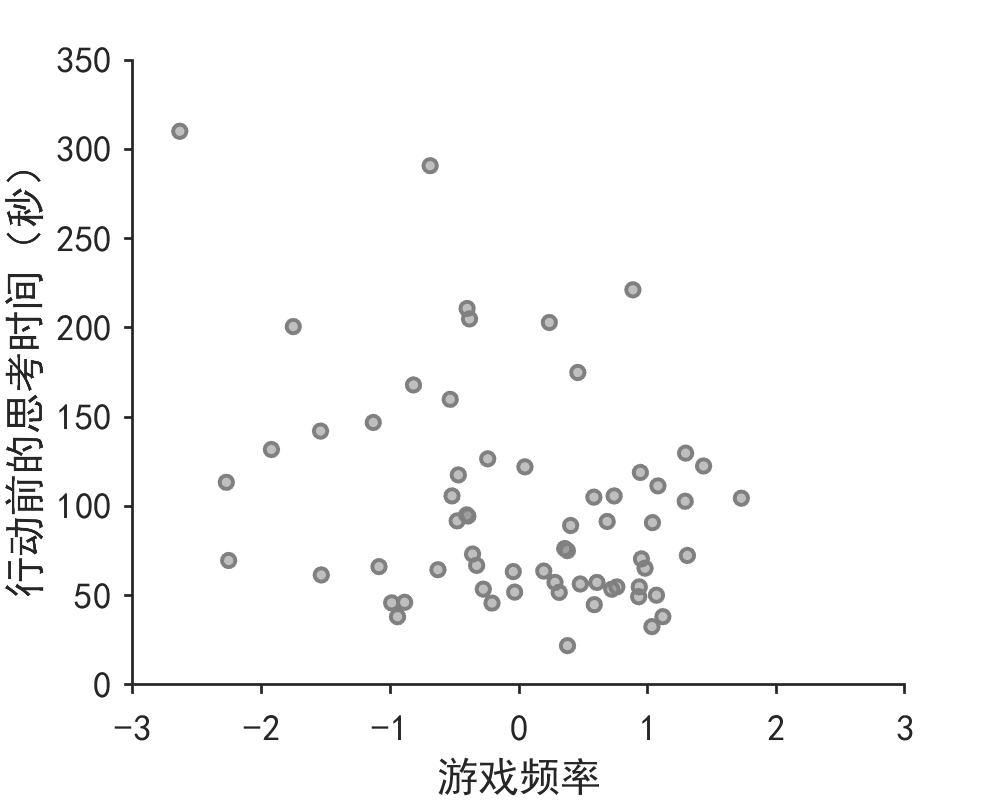

scatter(U.GameFreq, U.sum_Time2Initiate, 25, [0.5, 0.5, 0.5], 'MarkerFaceColor', 'flat', ...
                            'MarkerFaceAlpha', 0.5, 'LineWidth', 1.5);
set_figure_prop
legend off
xlabel('游戏频率')
ylabel('行动前的思考时间（秒）')
xlim([-3 3])

lmf = fitlme(U, 'sum_sum ~ GameFreq + GamePref')

lmf = Linear mixed-effects model fit by ML

Model information:
    Number of observations              64
    Fixed effects coefficients           3
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    sum_sum ~ 1 + GameFreq + GamePref

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    185.46    194.09    -88.729          177.46  

Fixed effects coefficients (95% CIs):
    Name                   Estimate       SE         tStat          DF    pValue      Lower       Upper   
    {'(Intercept)'}        -7.3624e-16      0.121    -6.0848e-15    61           1    -0.24195     0.24195
    {'GameFreq'   }           -0.21942    0.12195        -1.7992    61    0.076932    -0.46328    0.024441
    {'GamePref'   }           -0.00135    0.12195       -0.01107    61      0.9912    -0.24521     0.24251

Random effects covariance paramet

U.sum_Time2Win = zscore(U.sum_Time2Win);
U.sum_Time2Initiate = ore(U.sum_Time2Initiate);
U.sum_Time4Revisit = zscore(U.sum_Time4Revisit);
lmf = fitlme(U, 'sum_Time2Win ~ GameFreq + GamePref')

lmf = Linear mixed-effects model fit by ML

Model information:
    Number of observations              64
    Fixed effects coefficients           3
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    sum_Time2Win ~ 1 + GameFreq + GamePref

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    186.18    194.81    -89.088          178.18  

Fixed effects coefficients (95% CIs):
    Name                   Estimate       SE         tStat          DF    pValue     Lower       Upper   
    {'(Intercept)'}        -3.6828e-18    0.12168    -3.0267e-17    61          1    -0.24331     0.24331
    {'GameFreq'   }             -0.193    0.12264        -1.5737    61    0.12073    -0.43823    0.052235
    {'GamePref'   }          -0.013095    0.12264       -0.10678    61    0.91532    -0.25833     0.23214

Random effects covariance parame

lmf = fitlme(U, 'sum_Time2Initiate ~ GameFreq + GamePref')

lmf = Linear mixed-effects model fit by ML

Model information:
    Number of observations              64
    Fixed effects coefficients           3
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    sum_Time2Initiate ~ 1 + GameFreq + GamePref

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    181.52    190.16    -86.762          173.52  

Fixed effects coefficients (95% CIs):
    Name                   Estimate       SE         tStat          DF    pValue       Lower       Upper    
    {'(Intercept)'}        -1.9905e-17    0.11734    -1.6964e-16    61            1    -0.23463      0.23463
    {'GameFreq'   }           -0.31586    0.11826        -2.6708    61    0.0096871    -0.55234    -0.079377
    {'GamePref'   }            0.07157    0.11826        0.60518    61      0.54731    -0.16491      0.30805

Random effects 

lmf = fitlme(U, 'sum_Time4Revisit~ GameFreq + GamePref')

lmf = Linear mixed-effects model fit by ML

Model information:
    Number of observations              64
    Fixed effects coefficients           3
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    sum_Time4Revisit ~ 1 + GameFreq + GamePref

Model fit statistics:
    AIC       BIC      LogLikelihood    Deviance
    187.27    195.9    -89.633          179.27  

Fixed effects coefficients (95% CIs):
    Name                   Estimate       SE         tStat          DF    pValue     Lower       Upper  
    {'(Intercept)'}        -8.8037e-18    0.12272    -7.1739e-17    61          1    -0.24539    0.24539
    {'GameFreq'   }          -0.097725    0.12369       -0.79009    61    0.43253    -0.34505     0.1496
    {'GamePref'   }            0.10649    0.12369          0.861    61    0.39261    -0.14083    0.35382

Random effects covariance paramete

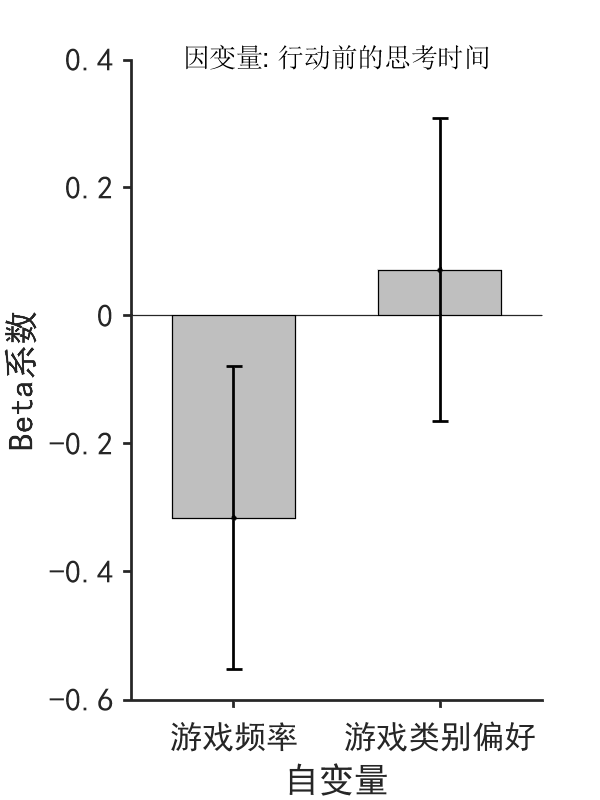


m = [-0.31586 0.07157];
neg = [-0.55234 -0.16491];
pos = [-0.079377 0.30805];

figure('Position', [0 0 300 400])

b = bar(m, 0.6); hold on
b.FaceColor = [0.75 0.75 0.75];
f = @(a)bsxfun(@plus,cat(1,a{:,1}),cat(1,a{:,2})).';
errorbar(f(get(b,{'xoffset','xdata'})),m,m - neg, pos - m,'.','Color','k','linewidth',1)
set_figure_prop
xlabel('自变量')
xlim([0.5 2.5])
xticklabels({'游戏频率' '游戏类别偏好'})
set(gca, 'FontSize', 12)
ylabel('Beta系数')
legend off

text(1.5,0.38,'因变量: 行动前的思考时间','HorizontalAlignment','center',...
    'VerticalAlignment','bottom')

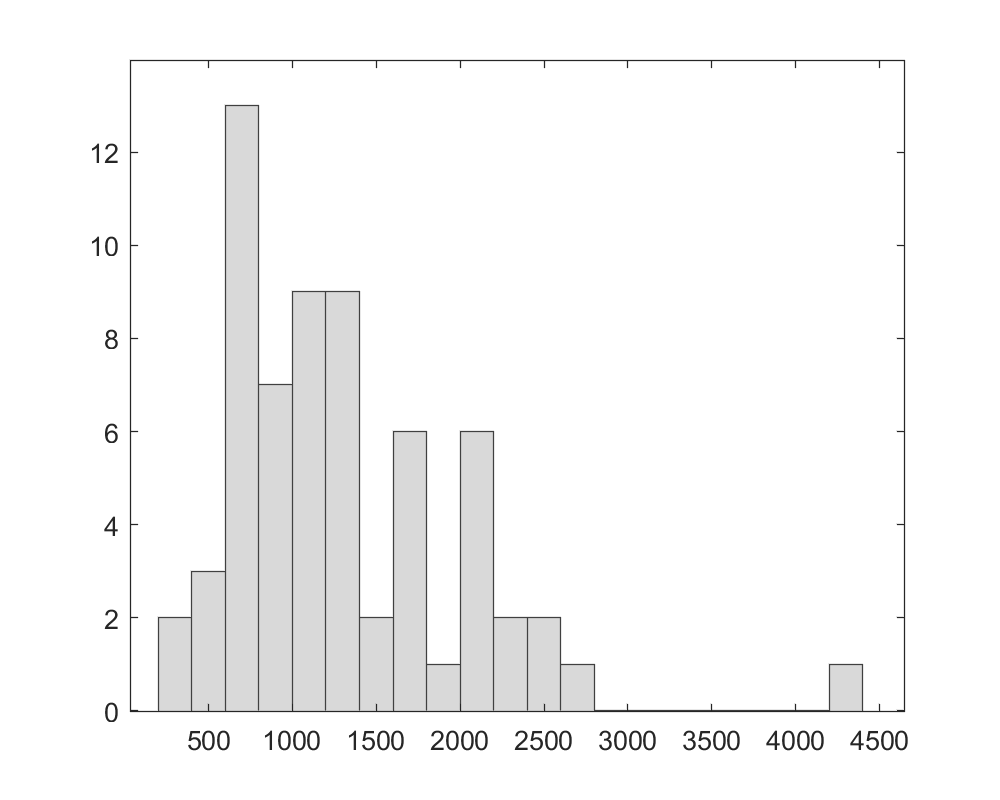

Q.beforeBonus = Q.TutorialTime + Q.PretestTime + Q.TrainingTime;
histogram(Q.beforeBonus, 'BinWidth',200, 'FaceColor',[0.75 0.75 0.75], 'EdgeColor',[0.25 0.25 0.25])

fitlme(Q, 'beforeBonus ~ GameFreq + GamePre')

ans = Linear mixed-effects model fit by ML

Model information:
    Number of observations              64
    Fixed effects coefficients           3
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    beforeBonus ~ 1 + GameFreq + GamePref

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    1026.2    1034.8    -509.11          1018.2  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat       DF    pValue        Lower      Upper 
    {'(Intercept)'}         1303.5     86.177      15.126    61    2.6049e-22     1131.2    1475.8
    {'GameFreq'   }        -63.255     86.858    -0.72826    61       0.46924    -236.94    110.43
    {'GamePref'   }        -65.818     86.858    -0.75776    61       0.45151     -239.5    107.87

Random effects covariance parameters (95% CIs):
Grou

fitlme(Q, 'TutorialTime ~ GameFreq + GamePref')

ans = Linear mixed-effects model fit by ML

Model information:
    Number of observations              64
    Fixed effects coefficients           3
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    TutorialTime ~ 1 + GameFreq + GamePref

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    846.04    854.67    -419.02          838.04  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat       DF    pValue        Lower      Upper 
    {'(Intercept)'}          284.7      21.09      13.499    61    5.5846e-20     242.52    326.87
    {'GameFreq'   }         -25.02     21.256      -1.177    61       0.24375    -67.525    17.485
    {'GamePref'   }        -12.138     21.256    -0.57104    61       0.57007    -54.643    30.367

Random effects covariance parameters (95% CIs):
Gro

fitlme(Q, 'PretestTime ~ GameFreq + GamePref')

ans = Linear mixed-effects model fit by ML

Model information:
    Number of observations              64
    Fixed effects coefficients           3
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    PretestTime ~ 1 + GameFreq + GamePref

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    989.31    997.94    -490.65          981.31  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat       DF    pValue        Lower      Upper 
    {'(Intercept)'}          596.9     64.592      9.2411    61    3.3374e-13     467.74    726.06
    {'GameFreq'   }         11.988     65.103     0.18415    61       0.85451    -118.19    142.17
    {'GamePref'   }        -23.881     65.103    -0.36682    61       0.71502    -154.06     106.3

Random effects covariance parameters (95% CIs):
Grou

fitlme(Q, 'TrainingTime ~ GameFreq + GamePref')

ans = Linear mixed-effects model fit by ML

Model information:
    Number of observations              64
    Fixed effects coefficients           3
    Random effects coefficients          0
    Covariance parameters                1

Formula:
    TrainingTime ~ 1 + GameFreq + GamePref

Model fit statistics:
    AIC       BIC       LogLikelihood    Deviance
    892.93    901.56    -442.46          884.93  

Fixed effects coefficients (95% CIs):
    Name                   Estimate    SE        tStat       DF    pValue        Lower      Upper 
    {'(Intercept)'}         421.91     30.421      13.869    61    1.6002e-20     361.08    482.74
    {'GameFreq'   }        -50.224     30.661      -1.638    61       0.10657    -111.53    11.087
    {'GamePref'   }        -29.799     30.661    -0.97187    61       0.33495     -91.11    31.512

Random effects covariance parameters (95% CIs):
Gro

X = S_noRep(:, {'SubNo', 'Level', 'Solution'});
U = unstack(X, 'Solution','Level');

try1 = arrayfun(@(x) strcmp(x, ''), U.x1);
try2 = arrayfun(@(x) strcmp(x, ''), U.x1) | arrayfun(@(x) strcmp(x, ''), U.x2);
try3 = arrayfun(@(x) strcmp(x, ''), U.x1) | arrayfun(@(x) strcmp(x, ''), U.x2) | arrayfun(@(x) strcmp(x, ''), U.x3);

## Figure 3A

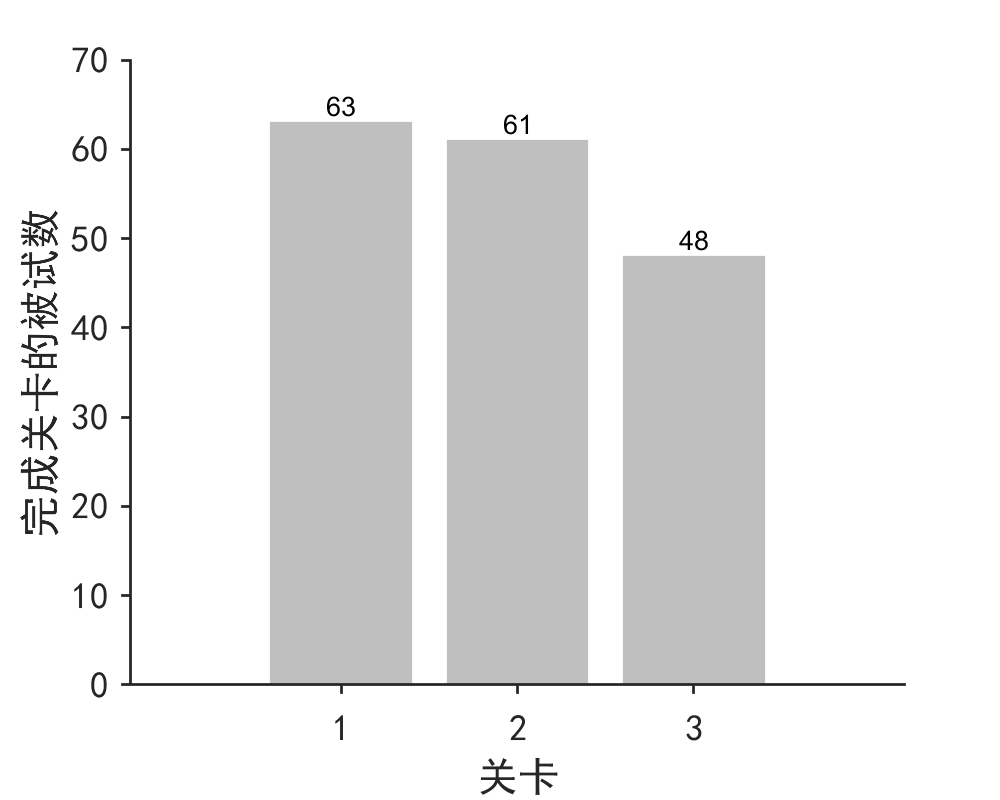

figure('Position', [0 0 500 400])

b = bar([sum(~try1) sum(~try2) sum(~try3)], 'FaceColor',[0.75 0.75 0.75], 'EdgeColor',"flat");
ylabel('完成关卡的被试数');
xlabel('关卡');
set_figure_prop;
legend off
xtips = b.XEndPoints;
ytips = b.YEndPoints;
labels = string(b.YData);
text(xtips,ytips,labels,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')

Figure 3B

S_noRep.SolutionType = categorical(S_noRep.Solution, solutionSet);
S_noRep.ConditionType = categorical(S_noRep.Condition, [1 2 3 4], conditionSet);

summaryTable = groupsummary(S_noRep, {'Level' 'SolutionType'}, 'IncludeEmptyGroups',true);
summaryCounts = permute(reshape(summaryTable.GroupCount, [4 3]),[2,1]);


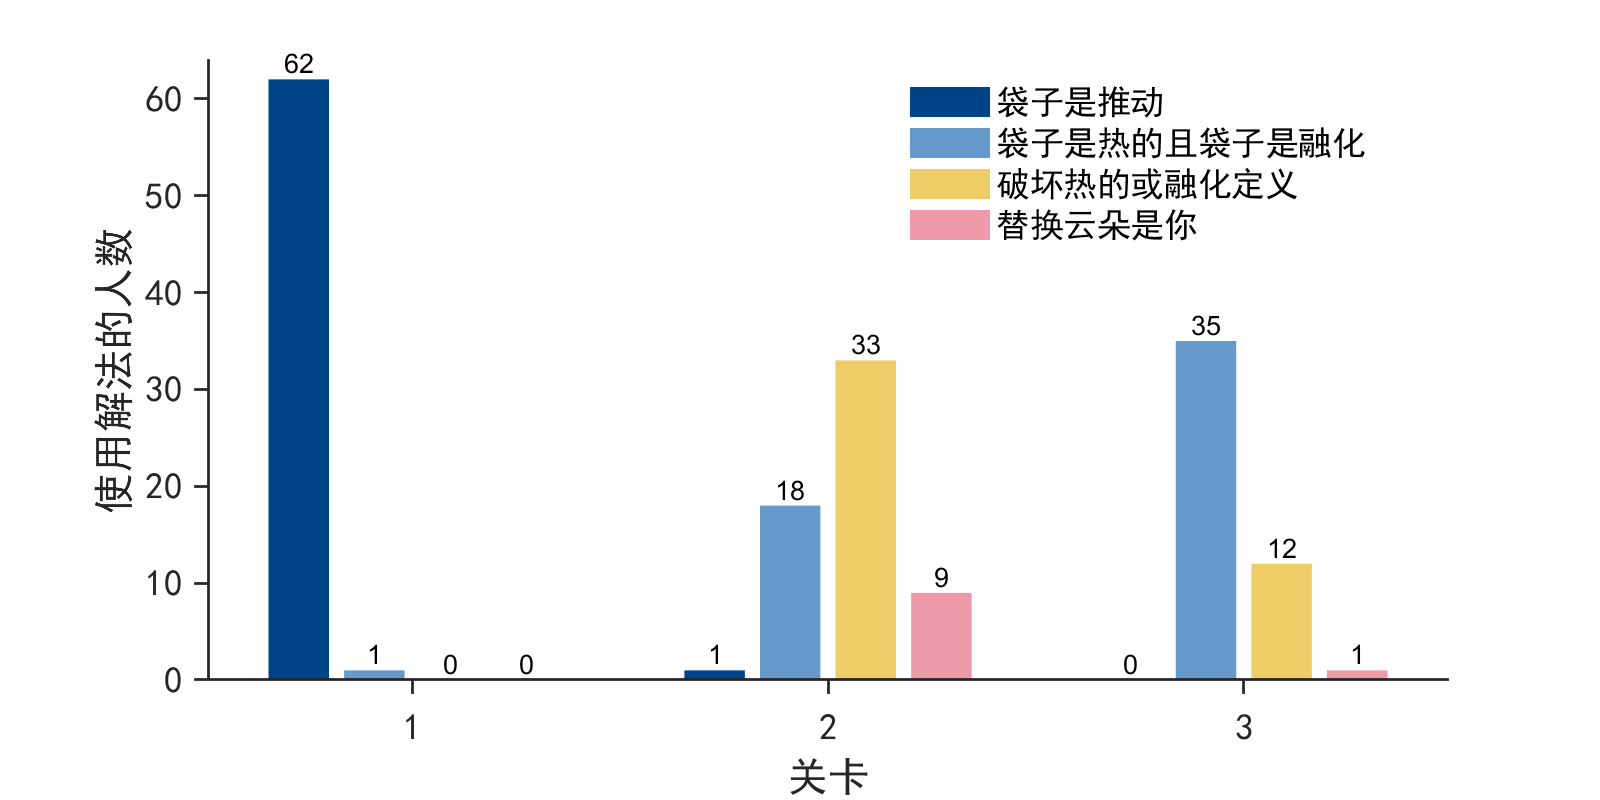

figure('Position', [100 100 800 400])
b = bar(summaryCounts,'grouped', 'EdgeColor',"none");

for k = 1:numel(solutionSet)
    b(k).FaceColor = Color4Solution(k, :);
    
    xtips = b(k).XEndPoints;
    ytips = b(k).YEndPoints;
    labels = string(b(k).YData);
    text(xtips,ytips,labels,'HorizontalAlignment','center',...
    'VerticalAlignment','bottom')
end

set_figure_prop;
legend({'袋子是推动', '袋子是热的且袋子是融化', '破坏热的或融化定义', '替换云朵是你'}, 'Location',"best");
ylabel('使用解法的人数');
xlabel('关卡');
ylim([0,64]);